# **Projet Étudiant - AU2**

# **LIMA MILITAO PINHEIRO Douglas**

close all; clear; clc;

## 1. Paramètres de l'éolienne

ro=1.3;
R1=12;
Jt=10;  kt=1e6;
G1=18;
Jm=0.2; fm=2;
Ja=0.6; fa=2; ka=5e4;

###     1.1. Fonction de transfert du système

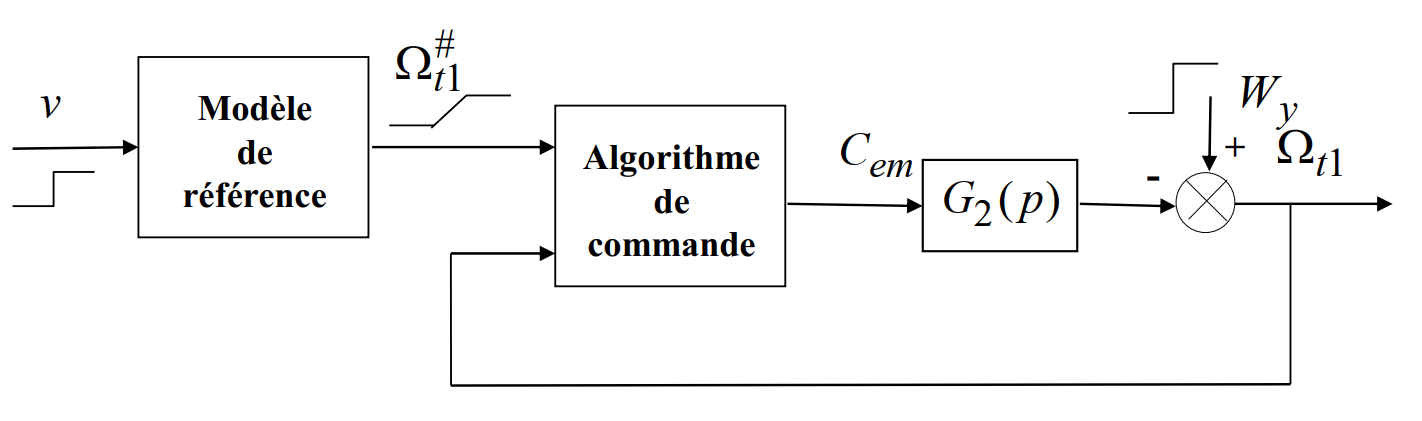

Schéma simplifié de commande

c0 = ka*kt;
c1 = G1^2*fm*ka+fa*(G1^2*ka+kt);
c2 = G1^2*fa*fm+G1^2*ka*(Ja+Jm)+kt*Ja;
c3 = G1^2*(fm*Ja+fa*Jm);
c4 = G1^2*Ja*Jm;
numG1 = [c4 c3 c2 c1 c0];

e0 = G1*ka*kt;
numG2 = [e0];

d0 = G1^2*ka*kt*(fm+fa);
d1 = kt*(G1^2*fa*fm+ka*(G1^2*(Ja+Jm)+Jt));
d2 = G1^2*fm*(ka*Jt+kt*Ja)+fa*(kt*Jt+G1^2*(ka*Jt+kt*Jm));
d3 = G1^2*fa*fm*Jt+kt*Ja*Jt+G1^2*(ka*Ja*Jt+ka*Jm*Jt+kt*Ja*Jm);
d4 = G1^2*Jt*(fm*Ja+fa*Jm);
d5 = G1^2*Ja*Jm*Jt;
den = [d5 d4 d3 d2 d1 d0];

Te = 5e-3;      %   Échantillonage 5ms
tsim = Te/100;  %   Temps pour collecter les données dans le simulink

%G1_tf = tf(numG1,den);

###     1.2. Analyse de stabilité des pôles et zéros


$$G_2 \left(p\right)=-\frac{e_0 }{d_0 +d_1 p+d_2 p^2 +d_3 p^3 +d_4 p^4 +d_5 p^5 }$$


G2 = tf(-1*numG2,den)   % Fonction de transfert G_2(p)

G2 =
 
                                    -9e11
  -------------------------------------------------------------------------
  388.8 s^5 + 5184 s^4 + 1.745e08 s^3 + 1.186e09 s^2 + 1.346e13 s + 6.48e13
 
Continuous-time transfer function.



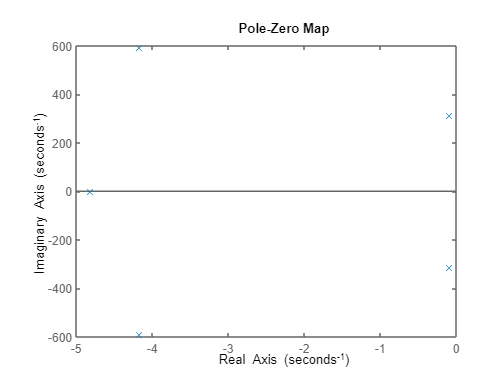

pzmap(G2)

***Pas de zéro, poles dans le plan à gauche, système stable !***

G2d = c2d(G2,Te,'zoh');  %
G2d.Variable = 'z^-1'    %  Discretisation du processus G2

G2d =
 
  -4.561e-05 z^-1 - 0.0006392 z^-2 - 0.001219 z^-3 - 0.0006232 z^-4 - 4.359e-05 z^-5
  ----------------------------------------------------------------------------------
      1 + 0.9537 z^-1 + 0.08266 z^-2 + 0.008003 z^-3 - 0.9237 z^-4 - 0.9355 z^-5
 
Sample time: 0.005 seconds
Discrete-time transfer function.



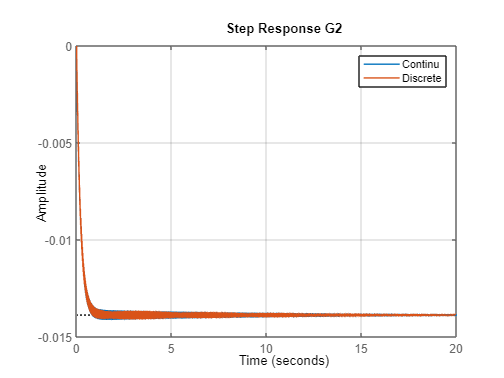

G2d.Variable = "z";
                                
figure                          %
hold on                         %
t = 0:1e-3:20;                  %
step(G2,t)                      %
step(G2d)                       %
legend("Continu","Discrete")    %   Plot step response continu et discrete (G2_p et G2_d)
title("Step Response G2")       %
grid on                         %
hold off                        %

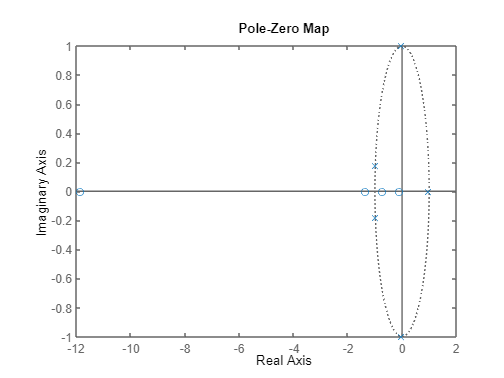

pzmap(G2d);     %   Zeros et poles du systeme sur plan Z

G2d_poles = pole(G2d)

G2d_poles =    0.9762 + 0.0000i
  -0.0022 + 0.9995i
  -0.0022 - 0.9995i
  -0.9628 + 0.1797i
  -0.9628 - 0.1797i


abs(G2d_poles) < 1

ans = 5×1 logical array
   1
   1
   1
   1
   1


***Tous les pôles sont à l'interieur du cercle unité, ainsi le système est stable en boucle ouverte***

G2d_zeros = zero(G2d)

G2d_zeros =   -11.8585
   -1.3585
   -0.7168
   -0.0828


***Tous les zéros sont réels à gauche du centre. On considére stable si ***$\sqrt{\;\beta^2 +\alpha {\;}^2 }<0\ldotp 5$

Bz_stable = abs(G2d_zeros) < 0.5

Bz_stable = 4×1 logical array
   0
   0
   0
   1


[G2d_num, G2d_den] = tfdata(G2d,'v');
Bz_stable = poly(G2d_zeros(find(Bz_stable,1):end))

Bz_stable =     1.0000    0.0828


Bz_instable = deconv(G2d_num,Bz_stable)

Bz_instable =          0   -0.0000   -0.0006   -0.0012   -0.0005


###     1.3. Analyse en frequénce

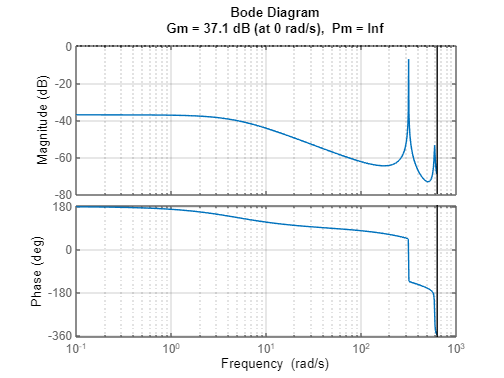

margin(G2d)     %Marge de Gain et de Phase
grid on

allmargin(G2d)

ans = struct with fields:
     GainMargin: [72.0000 2.5772e+03]
    GMFrequency: [0 565.5742]
    PhaseMargin: [1×0 double]
    PMFrequency: [1×0 double]
    DelayMargin: [1×0 double]
    DMFrequency: [1×0 double]
         Stable: 1


***Systeme vraiment stable !***

###     1.4. Génération de Omega - $\Omega_{t1}^\#$

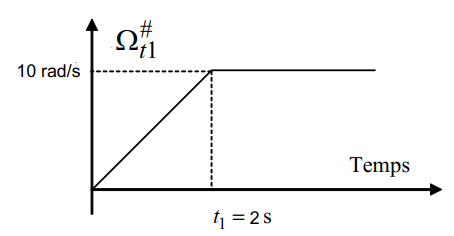

Montée en vitesse souhaitée

d = 2/Te;                           % Retard divisé pour échantillonage
z=tf('z',Te);                       %
G = (2/d)*(1-z^-d)/(1-z^-1)         % Fonction de transfert discret

G =
 
  0.005 z^401 - 0.005 z
  ---------------------
      z^401 - z^400
 
Sample time: 0.005 seconds
Discrete-time transfer function.



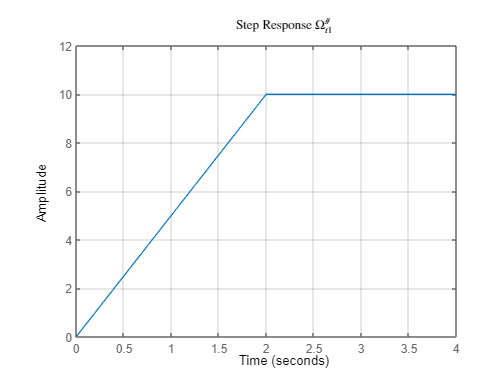

[Bm_omega, Am_omega] = tfdata(G,'v');

opt = stepDataOptions;                          %
opt.StepAmplitude = 5;                          % 
step(G,opt)                                     %  Step response avec échelon d'amplitude 5
grid on                                         %
axis([0 4 0 12])                                %
title("Step Response $\Omega^\#_{t1}$","Interpreter","latex") %

### ***    1.5. Cahiers des Charges***

####         1.5.1. Regulation (Ennoncé)

- Rejet d’une perturbation  avec un dynamique du deuxième ordre caractérisée par un temps de rejection à 5% de 150 ms.  

t_reg = 150e-3;                  % temp souhaité
xi_cdc = 0.7;                    % depassement 4.6% < 5%
wn_cdc = 2.90/t_reg;             % calcul du wn
 
CdC_reg = tf(1,[1/wn_cdc^2 2*xi_cdc/wn_cdc 1])

CdC_reg =
 
               1
  ----------------------------
  0.002675 s^2 + 0.07241 s + 1
 
Continuous-time transfer function.



stepinfo(CdC_reg,"SettlingTimeThreshold",0.05)  % Des informations d'une step response à 5%

ans = struct with fields:
         RiseTime: 0.1100
    TransientTime: 0.1500
     SettlingTime: 0.1500
      SettlingMin: 0.9001
      SettlingMax: 1.0460
        Overshoot: 4.5986
       Undershoot: 0
             Peak: 1.0460
         PeakTime: 0.2280


####         **1.5.2. Asservissement (Critère du concepteur)**

- Asservissement de premier ordre avec constant de temp dix fois plus petit que regulation

t_ass = t_reg/10;

CdC_ass = tf(1,[t_ass 1])

CdC_ass =
 
       1
  -----------
  0.015 s + 1
 
Continuous-time transfer function.



stepinfo(CdC_ass,"SettlingTimeThreshold",0.05) % Des informations d'une step response à 5%

ans = struct with fields:
         RiseTime: 0.0330
    TransientTime: 0.0449
     SettlingTime: 0.0449
      SettlingMin: 0.9045
      SettlingMax: 1.0000
        Overshoot: 0
       Undershoot: 0
             Peak: 1.0000
         PeakTime: 0.1582


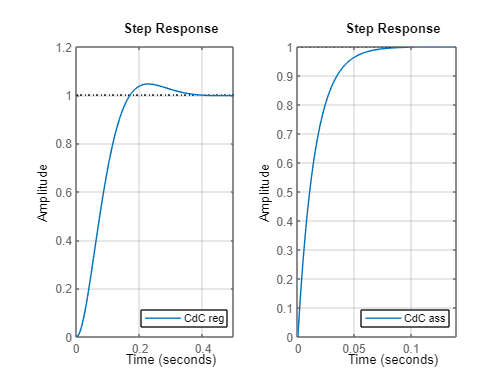

subplot(1,2,1)
hold on
step(CdC_reg)
legend("CdC reg",'location','southeast')
grid on
hold off
subplot(1,2,2)
hold on
step(CdC_ass)
legend("CdC ass",'location','southeast')
grid on
hold off

## ***2. Méthode de placement des pôles et zéros***

###     2.1. Traduction du Cahier de Charges

close all
CdCz_reg_PP = c2d(CdC_reg,Te,'zoh')

CdCz_reg_PP =
 
  0.004465 z + 0.004268
  ----------------------
  z^2 - 1.865 z + 0.8734
 
Sample time: 0.005 seconds
Discrete-time transfer function.



[CdCz_reg_num_PP, CdCz_reg_den_PP] = tfdata(CdCz_reg_PP,'v');

Gamma_PP = tf(sum(CdCz_reg_num_PP),CdCz_reg_den_PP,Te)      % Reponse souhaitée en boucle fermée

Gamma_PP =
 
         0.008733
  ----------------------
  z^2 - 1.865 z + 0.8734
 
Sample time: 0.005 seconds
Discrete-time transfer function.



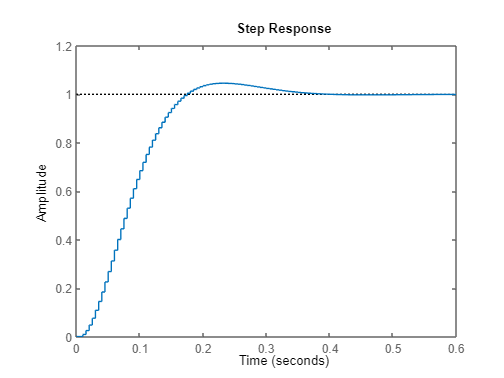

step(Gamma_PP)

### **    2.2. Adaptation du Cahier de Charges prise en compte des zéros instables**


$$\Gamma {\;}_a \left(z\right)=\frac{B_i \left(z\right)}{B_i \left(1\right)}\frac{1}{z^{-1} }\Gamma \;\left(z\right)\;$$


GammaA_PP = tf([Bz_instable 0],[sum(Bz_instable) zeros(1,length(Bz_instable)-1)],Te)*Gamma_PP

GammaA_PP =
 
  3.983e-07 z^4 + 5.549e-06 z^3 + 1.019e-05 z^2 + 4.599e-06 z
  -----------------------------------------------------------
          0.002374 z^6 - 0.004428 z^5 + 0.002074 z^4
 
Sample time: 0.005 seconds
Discrete-time transfer function.



###     2.3. Calcul du Correcteur


$$K\left(z\right)=\frac{1}{G_{2d} \left(z\right)}\frac{\Gamma {\;}_a \left(z\right)\;}{1-\Gamma {\;}_a \left(z\right)}$$


K_PP = minreal((1/G2d)*(GammaA_PP/(1-GammaA_PP)))

K_PP =
 
          -3.678 z^5 - 3.508 z^4 - 0.304 z^3 - 0.02943 z^2 + 3.397 z + 3.441
  ----------------------------------------------------------------------------------
  z^6 - 1.782 z^5 + 0.7189 z^4 + 0.06995 z^3 - 0.004485 z^2 - 0.002292 z - 0.0001603
 
Sample time: 0.005 seconds
Discrete-time transfer function.



[K_num_PP,K_den_PP] = tfdata(K_PP,'v');

###     2.4. Analyse de robustesse

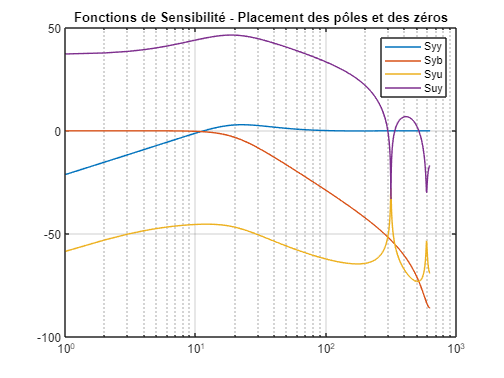

Lyy_PP = minreal(K_PP*G2d);             %
Syy_PP = minreal(1/(1+Lyy_PP));         %
Syb_PP = minreal(Syy_PP-1);             % Fonctions de sensibilité
Syu_PP = minreal(G2d*Syy_PP);           %
Suy_PP = minreal(-K_PP*Syy_PP);         %

w = 0:ceil(pi/Te);
[magSyy_PP,~,woutSyy_PP] = bode(Syy_PP,w);
[magSyb_PP,~,woutSyb_PP] = bode(Syb_PP,w);
[magSyu_PP,~,woutSyu_PP] = bode(Syu_PP,w);
[magSuy_PP,~,woutSuy_PP] = bode(Suy_PP,w);


semilogx(woutSyy_PP,db(magSyy_PP(:)));
hold on; grid on
semilogx(woutSyb_PP,db(magSyb_PP(:)));
semilogx(woutSyu_PP,db(magSyu_PP(:)));
semilogx(woutSuy_PP,db(magSuy_PP(:)));
legend("Syy","Syb","Syu","Suy")
title("Fonctions de Sensibilité - Placement des pôles et des zéros")
hold off

***On remarque que pour des bruit de mesure sinusoïdale de 10Hz (~ 63 rad/s), il y a une atténuation proche de 20dB par rapport à la sortie (Spécification nº 5)***

db(magSyb_PP(1,1,64))

ans = -20.7132

delta_M_PP = 1/max(magSyy_PP(:)) % Marge de Module > 0.5

delta_M_PP = 0.7115

[~,delta_phi_PP,~,wc_PP] = margin(Lyy_PP);
delta_tau_PP = delta_phi_PP*(pi/180)/wc_PP % Marge de Retard

delta_tau_PP = 0.1005

###     2.5. Simulation avec Simulink

***Le consigne est un échelon d'amplitude 5. A 5s de simulation un bruit du type échelon est appliqué dans Wy. A 7s de simulation un bruit sinusoïdal d'amplitude 3 est appliqué dans Wb.***

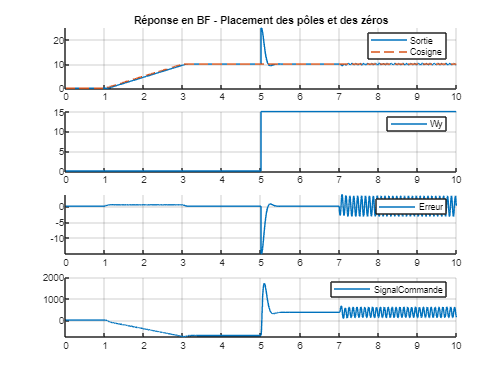

results_PP = sim("Projet_Placement_PZ_sim_LIMA_MILITAO_PINHEIRO.slx");
tout = 0:tsim:(length(results_PP.Sortie)-1)*tsim;


subplot(4,1,1)
hold on; grid on
plot(tout,results_PP.Sortie(:,1))
plot(tout,results_PP.Consigne(:,1),'--')
legend("Sortie","Cosigne")
title("Réponse en BF - Placement des pôles et des zéros")
hold off
subplot(4,1,2)
hold on; grid on
plot(tout,results_PP.Wy(:,1))
legend("Wy")
hold off
subplot(4,1,3)
hold on; grid on
plot(tout,results_PP.Erreur(:,1))
legend("Erreur")
hold off
subplot(4,1,4)
hold on; grid on
plot(tout,results_PP.SignalCommande(:,1))
legend("SignalCommande")
hold off

## ***3. Méthode de Commande par Modèle Interne***

close all

###     3.1. Annulation du comportement du systeme (sauf les zéros instables)

$C\left(z\right)=\frac{A\left(z\right)}{B\left(z\right)}\Gamma \;\left(z\right)=\frac{1}{G_{2d} \left(z\right)}\Gamma \;\left(z\right)$ où $\Gamma \;\left(z\right)=\frac{B_i \left(z\right)}{B_i \left(1\right)}$

Gamma_MI = tf(Bz_instable,[sum(Bz_instable) zeros(1,length(Bz_instable)-1)],Te)

Gamma_MI =
 
  4.561e-05 z^3 + 0.0006355 z^2 + 0.001167 z + 0.0005266
  ------------------------------------------------------
                       0.002374 z^4
 
Sample time: 0.005 seconds
Discrete-time transfer function.



Cz_MI = minreal(Gamma_MI/G2d)

Cz_MI =
 
  -421.2 z^5 - 401.6 z^4 - 34.81 z^3 - 3.37 z^2 + 389 z + 394
  -----------------------------------------------------------
                       z^5 + 0.08278 z^4
 
Sample time: 0.005 seconds
Discrete-time transfer function.



[Cz_num_MI, Cz_den_MI] = tfdata(Cz_MI,'v');

###     3.2. Traduction du Cahier de Charges de Regulation et Fonction F

CdCz_reg_MI = c2d(CdC_reg,Te,'zoh')

CdCz_reg_MI =
 
  0.004465 z + 0.004268
  ----------------------
  z^2 - 1.865 z + 0.8734
 
Sample time: 0.005 seconds
Discrete-time transfer function.



[CdCz_reg_num_MI, CdCz_reg_den_MI] = tfdata(CdCz_reg_MI,'v');


$$F\left(z\right)=\frac{{\textrm{CdC}}_{\textrm{reg}} \left(z\right)}{z^{-1} }$$


F_MI = tf([CdCz_reg_num_MI 0],CdCz_reg_den_MI,Te)

F_MI =
 
  0.004465 z^2 + 0.004268 z
  -------------------------
   z^2 - 1.865 z + 0.8734
 
Sample time: 0.005 seconds
Discrete-time transfer function.



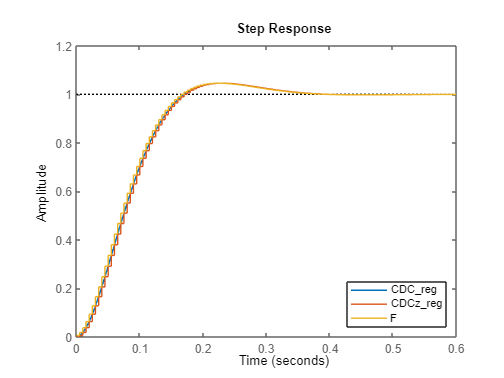

[F_num_MI, F_den_MI] = tfdata(F_MI,'v');
step(CdC_reg);
hold on
step(CdCz_reg_MI);
step(F_MI);
legend("CDC_reg","CDCz_reg","F","Location","southeast")
hold off

###     3.3. Traduction Cahier des Charges de Asservissement et Fonction G

CdCz_ass_MI = c2d(CdC_ass,Te,'zoh')

CdCz_ass_MI =
 
    0.2835
  ----------
  z - 0.7165
 
Sample time: 0.005 seconds
Discrete-time transfer function.



[CdCz_ass_num_MI, CdCz_ass_den_MI] = tfdata(CdCz_ass_MI,'v');


$$G\left(z\right)=\frac{{\textrm{CdC}}_{\textrm{ass}} \left(z\right)}{z^{-1} }$$


G_MI = tf([CdCz_ass_num_MI 0],CdCz_ass_den_MI,Te)

G_MI =
 
   0.2835 z
  ----------
  z - 0.7165
 
Sample time: 0.005 seconds
Discrete-time transfer function.



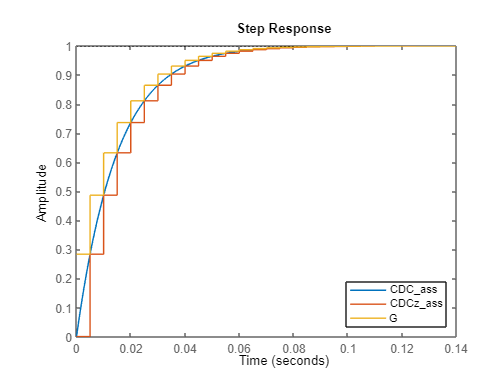

[G_num_MI, G_den_MI] = tfdata(G_MI,'v');
step(CdC_ass);
hold on
step(CdCz_ass_MI);
step(G_MI);
legend("CDC_ass","CDCz_ass","G","location","southeast")
hold off

###     3.4. Analyse de Robustesse

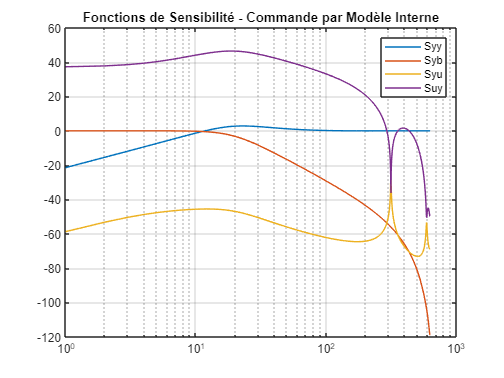

K_MI = Cz_MI*F_MI/(1-Cz_MI*F_MI*G2d);       % Calcul du correcteur équivalent

Lyy_MI = minreal(K_MI*G2d);                 %
Syy_MI = minreal(1/(1+Lyy_MI));             %
Syb_MI = minreal(Syy_MI-1);                 % Fonctions de sensibilité
Syu_MI = minreal(G2d*Syy_MI);               %
Suy_MI = minreal(-K_MI*Syy_MI);             %

w = 0:ceil(pi/Te);
[magSyy_MI,~,woutSyy_MI] = bode(Syy_MI,w);
[magSyb_MI,~,woutSyb_MI] = bode(Syb_MI,w);
[magSyu_MI,~,woutSyu_MI] = bode(Syu_MI,w);
[magSuy_MI,~,woutSuy_MI] = bode(Suy_MI,w);


semilogx(woutSyy_MI,db(magSyy_MI(:)));
hold on; grid on
semilogx(woutSyb_MI,db(magSyb_MI(:)));
semilogx(woutSyu_MI,db(magSyu_MI(:)));
semilogx(woutSuy_MI,db(magSuy_MI(:)));
legend("Syy","Syb","Syu","Suy")
title("Fonctions de Sensibilité - Commande par Modèle Interne")
hold off

***On remarque que pour des bruit de mesure sinusoïdale de 10Hz (~ 63 rad/s), il y a une atténuation proche de 20dB par rapport à la sortie (Spécification nº 5)***

db(magSyb_MI(1,1,64))

ans = -20.8213

delta_M_MI = 1/max(magSyy_MI(:)) % Marge de Module > 0.5

delta_M_MI = 0.7226

[~,delta_phi_MI,~,wc_MI]=margin(Lyy_MI);
delta_tau_MI = delta_phi_MI*(pi/180)/wc_MI % Marge de Retard

delta_tau_MI = 0.0987

###     3.5. Simulation avec Simulink

***Le consigne est un échelon d'amplitude 5. A 5s de simulation un bruit du type échelon est appliqué dans Wy. A 7s de simulation un bruit sinusoïdal d'amplitude 3 est appliqué dans Wb.***

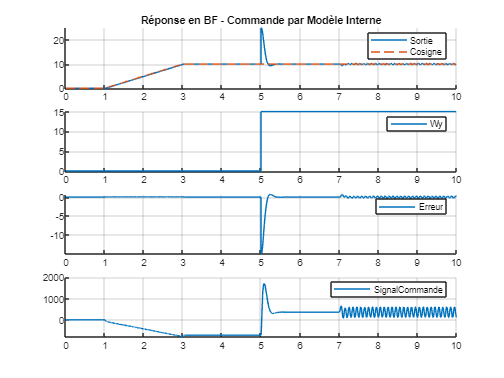

results_MI = sim("Projet_Modele_Interne_sim_LIMA_MILITAO_PINHEIRO.slx");
tout = 0:tsim:(length(results_MI.Sortie)-1)*tsim;

subplot(4,1,1)
hold on; grid on
plot(tout,results_MI.Sortie(:,1))
plot(tout,results_MI.Consigne(:,1),'--')
title("Réponse en BF - Commande par Modèle Interne")
legend("Sortie","Cosigne")
hold off
subplot(4,1,2)
hold on; grid on
plot(tout,results_MI.Wy(:,1))
legend("Wy")
hold off
subplot(4,1,3)
hold on; grid on
plot(tout,results_MI.Erreur(:,1))
legend("Erreur")
hold off
subplot(4,1,4)
hold on; grid on
plot(tout,results_MI.SignalCommande(:,1))
legend("SignalCommande")
hold off

## ***4. Commande RST***

close all

###     4.1. Traduction du Cahier de Charges

CdCz_RST = c2d(CdC_reg,Te,'zoh');
[~, P_cdc_r] = tfdata(CdCz_RST,'v');

###     4.2. Pré-caractérisation du Pz pour améliorer la réponse transitoire

Pz_RST = G2d_den;

###     4.3. Pré-caractérisation du S avec un intégrateur

Sp_RST = [1 -1];
Rp_RST = 1;

###     4.4. Montage de la matrice M

Cz_RST = conv(G2d_den,Sp_RST)'      

Cz_RST =     1.0000
   -0.0463
   -0.8710
   -0.0747
   -0.9317
   -0.0118
    0.9355


Ez_RST = conv(G2d_num,Rp_RST)'     % Considérant tous les zéros comme instables

Ez_RST =          0
   -0.0000
   -0.0006
   -0.0012
   -0.0006
   -0.0000


nc_RST = length(Cz_RST)-1;          %
ne_d_RST = length(Ez_RST)-1;        %
ns_RST = ne_d_RST - 1;              % Calcul du degré des polynômes
nr_RST = nc_RST - 1;                %
np_RST = nc_RST + ne_d_RST - 1;     %


M_RST = [];
for i = 1:ns_RST+1
    M_RST = [M_RST [zeros(i-1,1);Cz_RST;zeros(ns_RST-i+1,1)]];
end
for i = 1:nr_RST+1
    M_RST = [M_RST [zeros(i-1,1);Ez_RST(1:end);zeros(nr_RST-i+1,1)]];
end

M_RST

M_RST =     1.0000         0         0         0         0         0         0         0         0         0         0
   -0.0463    1.0000         0         0         0   -0.0000         0         0         0         0         0
   -0.8710   -0.0463    1.0000         0         0   -0.0006   -0.0000         0         0         0         0
   -0.0747   -0.8710   -0.0463    1.0000         0   -0.0012   -0.0006   -0.0000         0         0         0
   -0.9317   -0.0747   -0.8710   -0.0463    1.0000   -0.0006   -0.0012   -0.0006   -0.0000         0         0
   -0.0118   -0.9317   -0.0747   -0.8710   -0.0463   -0.0000   -0.0006   -0.0012   -0.0006   -0.0000         0
    0.9355   -0.0118   -0.9317   -0.0747   -0.8710         0   -0.0000   -0.0006   -0.0012   -0.0006   -0.0000
         0    0.9355   -0.0118   -0.9317   -0.0747         0         0   -0.0000   -0.0006   -0.0012   -0.0006
         0         0    0.9355   -0.0118   -0.9317         0         0         0   -0.0000   -0.0006   -

###     4.5. Vecteur P pré-caractérisation à haute fréquence

P_RST = conv(P_cdc_r, Pz_RST);
alpha = 0.5;
Pa_RST = [1 -alpha];
for i = 1:(np_RST-length(P_RST)+1)
    P_RST = conv(Pa_RST, P_RST);
end

P_RST'

ans =     1.0000
   -2.4110
    1.2943
    1.1119
   -2.3995
    2.7115
   -0.9890
   -1.5198
    1.8296
   -0.7300


###     4.6. Solution du système et des polynômes R, S et T

X_RST = M_RST\P_RST'

X_RST =     1.0000
   -2.3647
    2.0555
   -0.7787
    0.1092
   -0.4246
   -0.4049
   -0.0351
   -0.0034
    0.3922


D_RST = X_RST(1:ns_RST+1)';
F_RST = X_RST(ns_RST+2:end)';
S = conv(Sp_RST,D_RST)

S =     1.0000   -3.3647    4.4202   -2.8342    0.8879   -0.1092


R = conv(F_RST,Rp_RST)

R =    -0.4246   -0.4049   -0.0351   -0.0034    0.3922    0.3972


T = P_RST/sum(G2d_num)

T = 1.0e+03 *

   -0.3890    0.9378   -0.5034   -0.4325    0.9333   -1.0547    0.3847    0.5911   -0.7116    0.2840   -0.0397


###     4.7. Traduction Cahier des Charges de Asservissement et Fonction G


$$G\left(z\right)=\frac{{\textrm{CdC}}_{\textrm{ass}} \left(z\right)}{z^{-1} }$$


CdCz_ass_RST = c2d(CdC_ass,Te,'zoh')

CdCz_ass_RST =
 
    0.2835
  ----------
  z - 0.7165
 
Sample time: 0.005 seconds
Discrete-time transfer function.



[CdCz_ass_num_RST, CdCz_ass_den_RST] = tfdata(CdCz_ass_RST,'v');
G_RST = tf([CdCz_ass_num_RST 0], CdCz_ass_den_RST,Te)

G_RST =
 
   0.2835 z
  ----------
  z - 0.7165
 
Sample time: 0.005 seconds
Discrete-time transfer function.



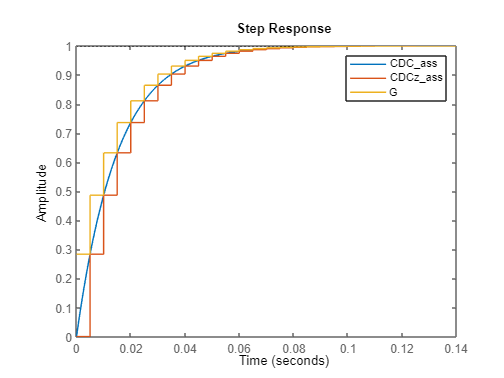

[G_num_RST, G_den_RST] = tfdata(G_RST,'v');
step(CdC_ass);
hold on
step(CdCz_ass_RST);
step(G_RST);
legend("CDC_ass","CDCz_ass","G")
hold off

###     4.8. Analyse de robustesse

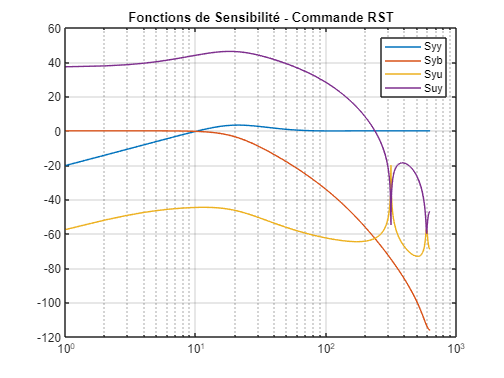

K_RST = tf(R,S,Te);                         % Calcul du correcteur équivalent

Lyy_RST = minreal(K_RST*G2d);               %
Syy_RST = minreal(1/(1+Lyy_RST));           %
Syb_RST = minreal(Syy_RST-1);               % Fonctions de sensibilité
Syu_RST = minreal(G2d*Syy_RST);             %
Suy_RST = minreal(-K_RST*Syy_RST);          %

w = 0:ceil(pi/Te);
[magSyy_RST,~,woutSyy_RST] = bode(Syy_RST,w);
[magSyb_RST,~,woutSyb_RST] = bode(Syb_RST,w);
[magSyu_RST,~,woutSyu_RST] = bode(Syu_RST,w);
[magSuy_RST,~,woutSuy_RST] = bode(Suy_RST,w);


semilogx(woutSyy_RST,db(magSyy_RST(:)));
hold on; grid on
semilogx(woutSyb_RST,db(magSyb_RST(:)));
semilogx(woutSyu_RST,db(magSyu_RST(:)));
semilogx(woutSuy_RST,db(magSuy_RST(:)));
legend("Syy","Syb","Syu","Suy")
title("Fonctions de Sensibilité - Commande RST")
hold off

***On remarque que pour des bruit de mesure sinusoïdale de 10Hz (~ 63 rad/s), il y a une atténuation plus grande que 20dB par rapport à la sortie (Spécification nº 5)***

db(magSyb_RST(1,1,64))

ans = -23.0843

delta_M_RST = 1/max(magSyy_RST(:)) % Marge de Module > 0.5

delta_M_RST = 0.6820

[~,delta_phi_RST,~,wc_RST]=margin(Lyy_RST);
delta_tau_RST = delta_phi_RST*(pi/180)/wc_RST % Marge de Retard

delta_tau_RST = 0.1095

###     4.9. Simulation avec Simulink

***Le consigne est un échelon d'amplitude 5. A 5s de simulation un bruit du type échelon est appliqué dans Wy. A 7s de simulation un bruit sinusoïdal d'amplitude 3 est appliqué dans Wb.***

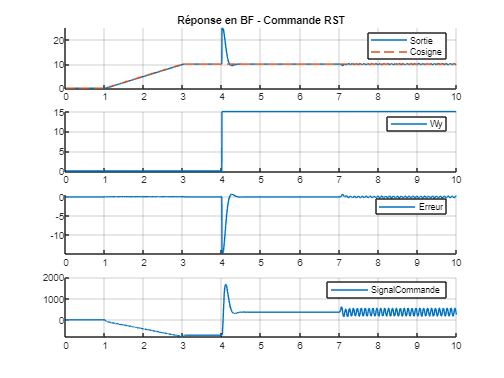

results_RST = sim("Projet_RST_sim_LIMA_MILITAO_PINHEIRO.slx");
tout = 0:tsim:(length(results_RST.Sortie)-1)*tsim;

subplot(4,1,1)
hold on; grid on
plot(tout,results_RST.Sortie(:,1))
plot(tout,results_RST.Consigne(:,1),'--')
legend("Sortie","Cosigne")
title("Réponse en BF - Commande RST")
hold off
subplot(4,1,2)
hold on; grid on
plot(tout,results_RST.Wy(:,1))
legend("Wy")
hold off
subplot(4,1,3)
hold on; grid on
plot(tout,results_RST.Erreur(:,1))
legend("Erreur")
hold off
subplot(4,1,4)
hold on; grid on
plot(tout,results_RST.SignalCommande(:,1))
legend("SignalCommande")
hold off

## **5. Discussion sur performances**

En observant le comportement de régulation, les trois correcteurs présentent approximativement la même caractéristique de réjection du bruit Wy. Cependant, le modèle por placement des pôles et des zéros présente la plus mauvaise performance de suivi de référence pendant l'entrée de la rampe par rapport aux autres. En outre, le contrôleur RST, pour avoir une caractérisation de rejet de bruit à haute fréquence sur le mesure, a une atténuation plus élevée par rapport au modèle interne du bruit Wb, et sera donc adopté pour contrôler le modèle complet.

## 6. Modèle Détaillé avec RST sans pré-caractérisation du R

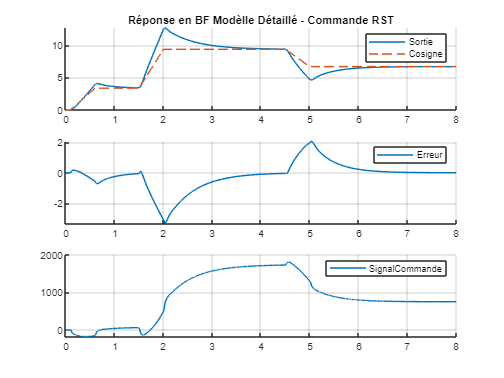

close all

warning('off','all')
sim("modele_detaille_sans_correcteur_LIMA_MILITAO_PINHEIRO.slx");
sim("modele_detaille_LIMA_MILITAO_PINHEIRO.slx");
warning('on','all')
tout = 0:tsim:(length(SortieWt1)-1)*tsim;

subplot(3,1,1)
hold on; grid on
plot(tout,SortieWt1)
plot(tout,ConsigneWt1,'--')
legend("Sortie","Cosigne")
title("Réponse en BF Modèlle Détaillé - Commande RST")
hold off
subplot(3,1,2)
hold on; grid on
plot(tout,ErreurWt1)
legend("Erreur")
hold off
subplot(3,1,3)
hold on; grid on
plot(tout,CommandeWt1)
legend("SignalCommande")
hold off

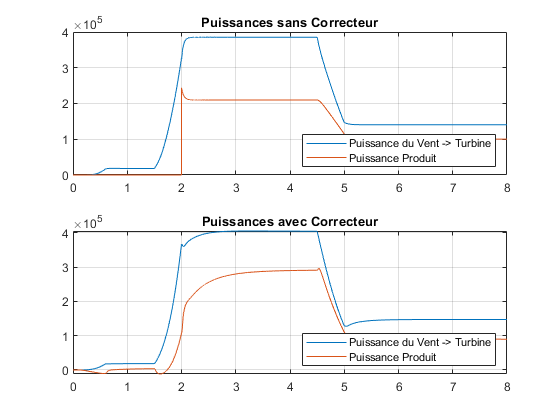

figure
subplot(2,1,1)
plot(tout,[PuissanceVentaTurbine_sansCorrecteur PuissanceProduit_sansCorrecteur])
legend("Puissance du Vent -> Turbine","Puissance Produit",'location','southeast')
title("Puissances sans Correcteur")
grid on

subplot(2,1,2)
plot(tout,[PuissanceVentaTurbine PuissanceProduit])
legend("Puissance du Vent -> Turbine","Puissance Produit",'location','southeast')
title("Puissances avec Correcteur")
grid on

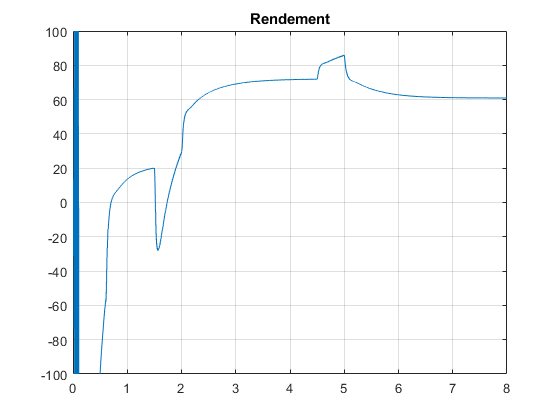

figure
plot(tout,Rendement*100)
title("Rendement")
axis([0 8 -100 100])
grid on

## 7. Algorithme de commande correspondant du RST sans pré-caractérisation du R

close all

**Algorithme mise en oeuvre dans la MATLAB Function**

**R, S, T, Sortie, Consigne, Gref_Ant et CommandeAnt sont des vecteurs de mesure et memoire**

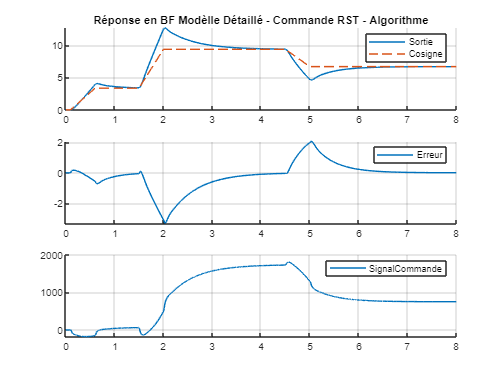

%
% function [Gcom, Commande] = fcn(Consigne, Gref_Ant, R, S, T, Gden, Gnum, Sortie, CommandeAnt)
%
% Gcom = Gden(1)*Consigne - Gnum(2)*Gref_Ant(1);
% Tcom = T(1)*Gcom;
% Rcom = 0;
%
% for i=2:length(T)
%    Tcom = Tcom + T(i)*Gref_Ant(i-1);
% end
%
% for i=1:length(R)
%    Rcom = Rcom + R(i)*Sortie(i);
% end
%
% Commande = Tcom - Rcom;
%
% for i=1:length(CommandeAnt)
%    Commande = Commande - S(i+1)*CommandeAnt(i);
% end
%

warning('off','all')
sim("modele_detaille_algorithme_LIMA_MILITAO_PINHEIRO.slx");
warning('on','all')
tout = 0:tsim:(length(SortieWt1)-1)*tsim;

subplot(3,1,1)
hold on; grid on
plot(tout,SortieWt1)
plot(tout,ConsigneWt1,'--')
legend("Sortie","Cosigne")
title("Réponse en BF Modèlle Détaillé - Commande RST - Algorithme")
hold off
subplot(3,1,2)
hold on; grid on
plot(tout,ErreurWt1)
legend("Erreur")
hold off
subplot(3,1,3)
hold on; grid on
plot(tout,CommandeWt1)
legend("SignalCommande")
hold off

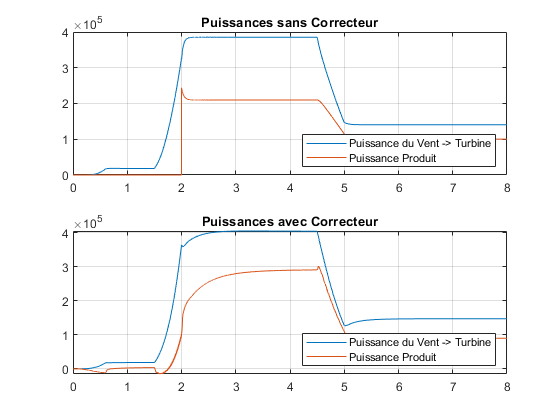

figure
subplot(2,1,1)
plot(tout,[PuissanceVentaTurbine_sansCorrecteur PuissanceProduit_sansCorrecteur])
legend("Puissance du Vent -> Turbine","Puissance Produit",'location','southeast')
title("Puissances sans Correcteur")
grid on

subplot(2,1,2)
plot(tout,[PuissanceVentaTurbine PuissanceProduit])
legend("Puissance du Vent -> Turbine","Puissance Produit",'location','southeast')
title("Puissances avec Correcteur")
grid on

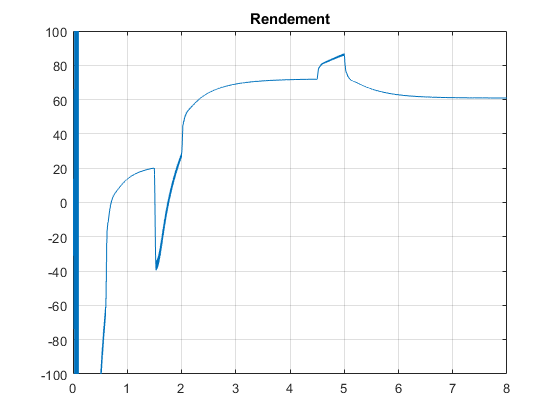

figure
plot(tout,Rendement*100)
title("Rendement")
axis([0 8 -100 100])
grid on

## ***8. Commande RST avec pré-caractérisation du R (BONUS)***

close all

###     8.1. Traduction du Cahier de Charges

CdCz_reg_RSTa = c2d(CdC_reg,Te,'zoh');
[~, P_cdc_r] = tfdata(CdCz_reg_RSTa,'v');

###     8.2. Pré-caractérisation du Pz pour améliorer la réponse transitoire

Pz_RSTa = G2d_den;

###     8.3. Pré-caractérisation du S avec un intégrateur et R

- Rejet d’une perturbation sinusoïdale à 10 Hz sur le bruit de mesure avec une atténuation d’environ -40 dB  

ws = 2*pi*10;
qsi = 0.01;
r = qsi*ws;
c = ws*sqrt(1-qsi^2);
alpha1 = -2*exp(-r*Te)*cos(Te*c);
alpha2 = exp(-2*r*Te);

Rp_RSTa = [1 alpha1 alpha2];
Sp_RSTa = [1 -1];

###     8.4. Montage de la matrice M

Cz_RSTa = conv(G2d_den,Sp_RSTa)'

Cz_RSTa =     1.0000
   -0.0463
   -0.8710
   -0.0747
   -0.9317
   -0.0118
    0.9355


Ez_RSTa = conv(G2d_num,Rp_RSTa)'

Ez_RSTa =          0
   -0.0000
   -0.0006
   -0.0001
    0.0011
   -0.0001
   -0.0005
   -0.0000


nc_RSTa = length(Cz_RSTa)-1;
ne_d_RSTa = length(Ez_RSTa)-1;
ns_RSTa = ne_d_RSTa - 1;
nr_RSTa = nc_RSTa - 1;
np_RSTa = nc_RSTa + ne_d_RSTa - 1;

M_RSTa = [];
for i = 1:ns_RSTa+1
    M_RSTa = [M_RSTa [zeros(i-1,1);Cz_RSTa;zeros(ns_RSTa-i+1,1)]];
end
for i = 1:nr_RSTa+1
    M_RSTa = [M_RSTa [zeros(i-1,1);Ez_RSTa(1:end);zeros(nr_RSTa-i+1,1)]];
end

M_RSTa

M_RSTa =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0463    1.0000         0         0         0         0         0   -0.0000         0         0         0         0         0
   -0.8710   -0.0463    1.0000         0         0         0         0   -0.0006   -0.0000         0         0         0         0
   -0.0747   -0.8710   -0.0463    1.0000         0         0         0   -0.0001   -0.0006   -0.0000         0         0         0
   -0.9317   -0.0747   -0.8710   -0.0463    1.0000         0         0    0.0011   -0.0001   -0.0006   -0.0000         0         0
   -0.0118   -0.9317   -0.0747   -0.8710   -0.0463    1.0000         0   -0.0001    0.0011   -0.0001   -0.0006   -0.0000         0
    0.9355   -0.0118   -0.9317   -0.0747   -0.8710   -0.0463    1.0000   -0.0005   -0.0001    0.0011   -0.0001   -0.0006   -0.0000
         0    0.9355   -0.0118   -0.9317   -0.0747   -0.8710   -0.0463   -

###     8.5. Vecteur P pré-caractérisation haute fréquence

P_RSTa = conv(P_cdc_r,Pz_RSTa);

alpha = 0.5;

Pa_RSTa = [1 -alpha];

for i = 1:(np_RSTa-length(P_RSTa)+1)
    P_RSTa = conv(Pa_RSTa, P_RSTa);
end
P_RSTa'

ans =     1.0000
   -3.4110
    3.9553
   -0.7851
   -3.1878
    5.3890
   -4.3004
    0.1471
    3.1021
   -2.9396


###     8.6. Solution du système et des polynômes R, S et T

X_RSTa = M_RSTa\P_RSTa'

X_RSTa =     1.0000
   -3.3647
    4.6698
   -3.4255
    1.4025
   -0.3033
    0.0273
   -1.0878
   -1.0374
   -0.0899


D_RSTa = X_RSTa(1:ns_RSTa+1)';
F_RSTa = X_RSTa(ns_RSTa+2:end)';
S = conv(Sp_RSTa,D_RSTa)

S =     1.0000   -4.3647    8.0346   -8.0953    4.8281   -1.7058    0.3306   -0.0273


R = conv(F_RSTa,Rp_RSTa)

R =    -1.0878    1.0252    0.7962   -0.8691    0.9320   -0.8963   -0.9311    1.0113


T = P_RSTa/sum(G2d_num)

T = 1.0e+03 *

   -0.3890    1.3268   -1.5385    0.3054    1.2399   -2.0961    1.6727   -0.0572   -1.2066    1.1434   -0.5016    0.1107   -0.0099


###     8.7. Traduction Cahier des Charges de Asservissement et Fonction G

CdCz_ass_RSTa = c2d(CdC_ass,Te,'zoh')

CdCz_ass_RSTa =
 
    0.2835
  ----------
  z - 0.7165
 
Sample time: 0.005 seconds
Discrete-time transfer function.



[CdCz_ass_num_RSTa, CdCz_ass_den_RSTa] = tfdata(CdCz_ass_RSTa,'v');
G_RSTa = tf([CdCz_ass_num_RSTa 0], CdCz_ass_den_RSTa,Te)

G_RSTa =
 
   0.2835 z
  ----------
  z - 0.7165
 
Sample time: 0.005 seconds
Discrete-time transfer function.



[G_num_RST, G_den_RST] = tfdata(G_RSTa,'v');
step(CdC_ass);
hold on
step(CdCz_ass_RSTa);
step(G_RSTa);
legend("CDC_ass","CDCz_ass","G")
hold off

###     8.8. Analyse de robustesse

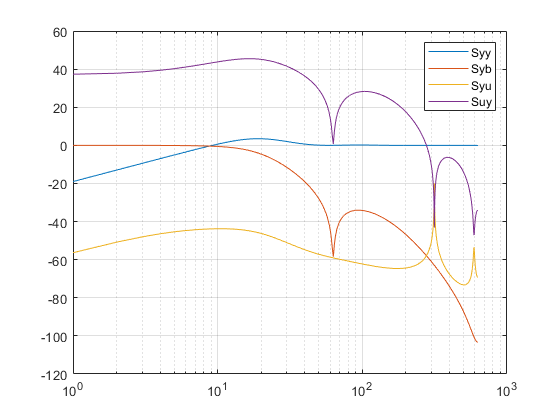

K_RSTa = tf(R,S,Te);                         % Calcul du correcteur équivalent

Lyy_RSTa = minreal(K_RSTa*G2d);               %
Syy_RSTa = minreal(1/(1+Lyy_RSTa));           %
Syb_RSTa = minreal(Syy_RSTa-1);               % Fonctions de sensibilité
Syu_RSTa = minreal(G2d*Syy_RSTa);             %
Suy_RSTa = minreal(-K_RSTa*Syy_RSTa);         %

w = 0:ceil(pi/Te);

[magSyy_RSTa,~,woutSyy_RSTa] = bode(Syy_RSTa,w);
[magSyb_RSTa,~,woutSyb_RSTa] = bode(Syb_RSTa,w);
[magSyu_RSTa,~,woutSyu_RSTa] = bode(Syu_RSTa,w);
[magSuy_RSTa,~,woutSuy_RSTa] = bode(Suy_RSTa,w);

figure
semilogx(woutSyy_RSTa,db(magSyy_RSTa(:)));
hold on; grid on
semilogx(woutSyb_RSTa,db(magSyb_RSTa(:)));
semilogx(woutSyu_RSTa,db(magSyu_RSTa(:)));
semilogx(woutSuy_RSTa,db(magSuy_RSTa(:)));
legend("Syy","Syb","Syu","Suy")
hold off

delta_M_RSTa = 1/max(magSyy_RSTa(:)) % Marge de Module > 0.5

delta_M_RSTa = 0.6695

[~,delta_phi_RSTa,~,wc_RSTa]=margin(Lyy_RSTa);
delta_tau_RSTa = delta_phi_RSTa*(pi/180)/wc_RSTa % Marge de Retard

delta_tau_RSTa = NaN

***On remarque que pour des bruit de mesure sinusoïdale de 10Hz (~ 63 rad/s), il y a une atténuation plus grande que 40dB par rapport à la sortie (Question BONUS)***

db(magSyb_RSTa(1,1,64))

ans = -58.3736

###     8.9. Simulation avec Simulink

***Le consigne est un échelon d'amplitude 5. A 5s de simulation un bruit du type échelon est appliqué dans Wy. A 7s de simulation un bruit sinusoïdal d'amplitude 3 est appliqué dans Wb.***

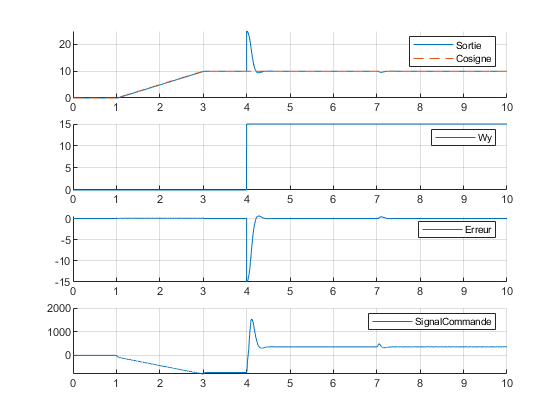

results_RSTa = sim("Projet_RST_sim_LIMA_MILITAO_PINHEIRO.slx");
tout = 0:tsim:(length(results_RSTa.Sortie)-1)*tsim;
figure
subplot(4,1,1)
hold on; grid on
plot(tout,results_RSTa.Sortie(:,1))
plot(tout,results_RSTa.Consigne(:,1),'--')
legend("Sortie","Cosigne")
hold off
subplot(4,1,2)
hold on; grid on
plot(tout,results_RSTa.Wy(:,1))
legend("Wy")
hold off
subplot(4,1,3)
hold on; grid on
plot(tout,results_RSTa.Erreur(:,1))
legend("Erreur")
hold off
subplot(4,1,4)
hold on; grid on
plot(tout,results_RSTa.SignalCommande(:,1))
legend("SignalCommande")
hold off

## 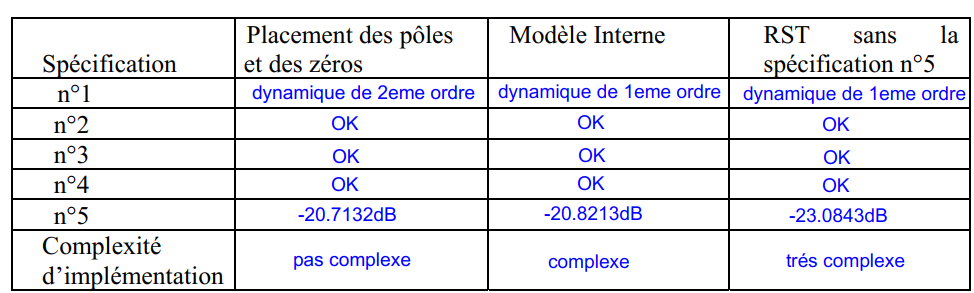

## 9. Conclusion

    Ce projet était important pour mettre en œuvre et maîtriser les sujets du cours vu en classe. Il a ainsi été possible d'évaluer les performances de différents types de correcteurs et de comprendre leurs avantages, leurs inconvénients, leurs complexité et leurs applications dans un modèle complexe. 

    Parmi les types de correcteurs utilisés, celui qui a donné les meilleurs résultats dans le modèle simplifié était le Commande RST, qui a correctement suivi la référence, a éliminé l'erreur en régime permanent et a rejeté les perturbations Wy et Wb comme imposé dans les Cahier des Charges. Cependant, en raison des non-linéarités du modèle réel, le résultat de sortie ne présente pas le même comportement que le modèle simplifié, mais il est toujours capable de bien contrôler le système et augmenter la production d'énergie et le rendement. 

    D'un autre point de vue, le sujet était également important pour développer des compétences dans le logiciel MATLAB/Simulink qui est largement utilisé dans le contexte professionnel comme un ingénieur.